# Lab 3 - Asking a statistical question

Thomas Conaway

Lab Partners: Jeff Jiang, Avi Soval

Time: 10 hours (including lab time)

## Problem 1

When collecting data points it is possible for "bad data" to be introduced whenever glitches or errors occur. We would like to be able to identify and throw away points which are obviously anomalous. On a histogram modelled by a probability distribution, values which lie far out in the tails are likely candidates for removal, as it is unlikely that our chosen distribution model will produce them randomly.

For an experiment which requires a consistent 12 K temperature to perform reliably, we can examine the temperature meta-data to look for instances where the temperature varied significantly from 12 K and throw out this data. It is still possible that good data may be lost, such as when the measured temperature was wrong but the real temperature was within bounds, but without any way of knowing that this happened we will have to accept this loss as the cost of removing the bad data.

To explore the consequences of this further, I will assess the 12 K temperature scenario above using randomly generated data. I will generate 100,000 random "good" data points that will be Gaussian distributed around a mean of 12 K with a standard deviation 0.4 K (the precision of the thermometry and the thermal control system). I will then toss in some bad data, and will attempt to identify it within the distribution and throw it out.

A) Generating data and plotting it in histograms:

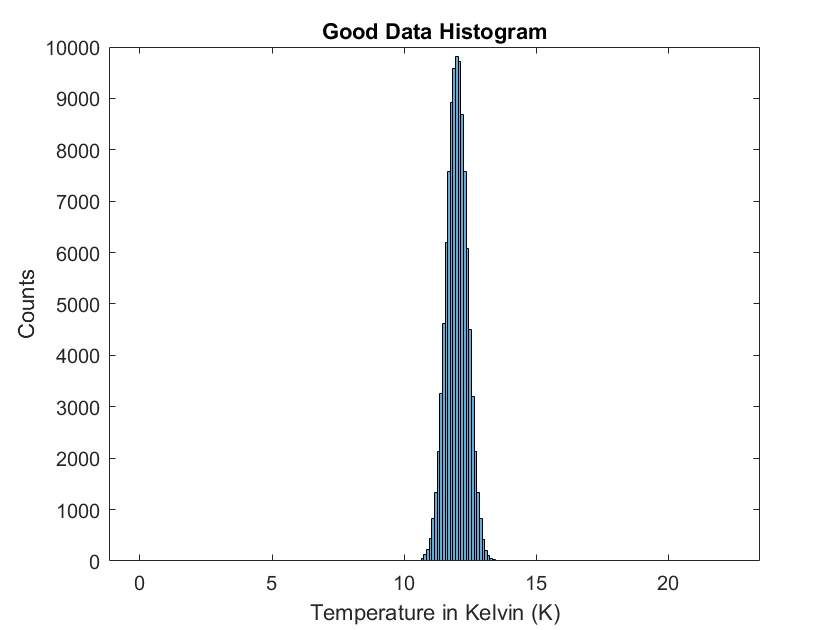

clc; clear; close all;
gooddist = random("Normal",12,0.4,[1,100000]);
% testdist = round(gooddist,1)
badpoints = [10.,10.3,2.1,0.,0.,15.6,22.3,12.7]; % 8 total
baddist = [gooddist,badpoints];
bins = 0:0.1:22.4;
bins = bins - 0.05;
histogram(gooddist,bins);
% xlim([10,14]);
title("Good Data Histogram");
xlabel("Temperature in Kelvin (K)");
ylabel("Counts");

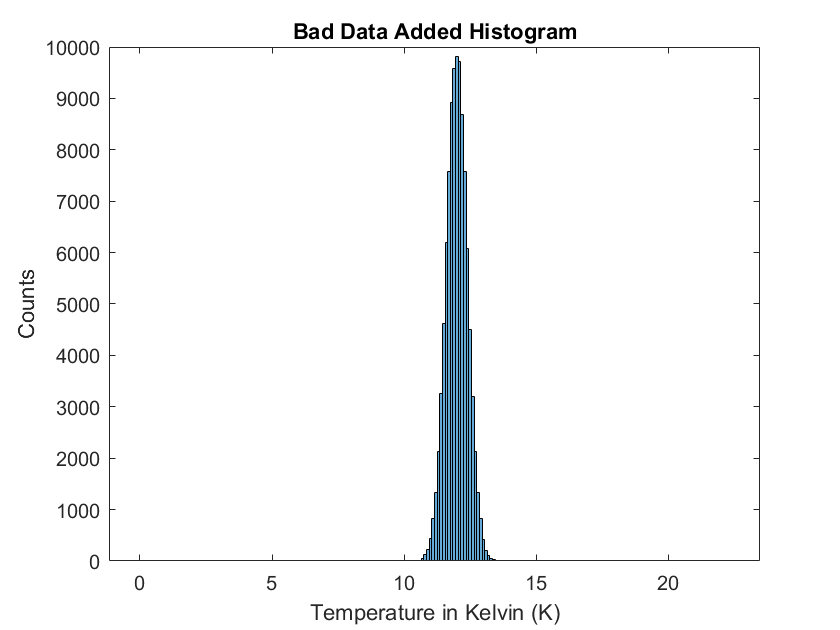

histogram(baddist,bins);
title("Bad Data Added Histogram");
xlabel("Temperature in Kelvin (K)");
ylabel("Counts");

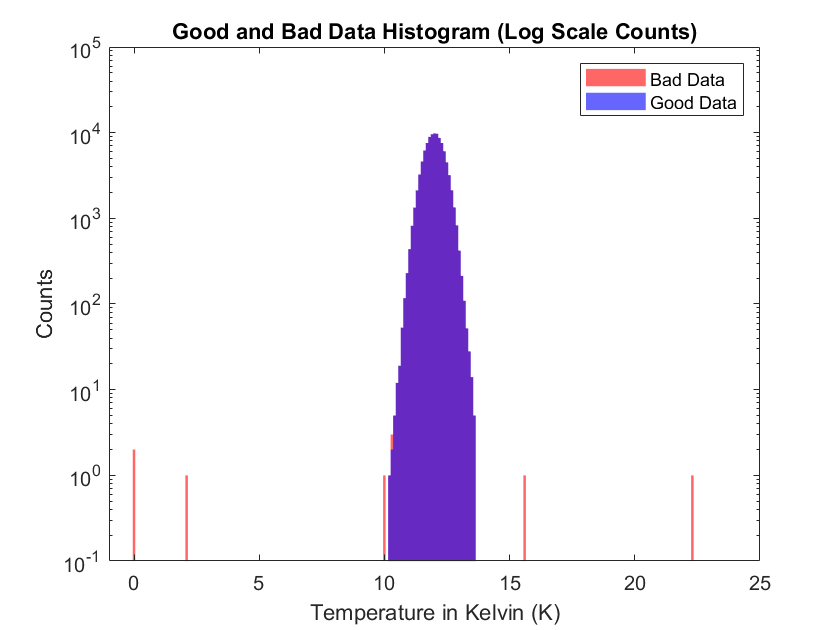

histogram(baddist,bins,"EdgeColor",'none',"FaceColor",'red');
hold on;
histogram(gooddist,bins,"EdgeColor",'none',"FaceColor",'blue');
set(gca,'YScale','log');
title("Good and Bad Data Histogram (Log Scale Counts)");
xlabel("Temperature in Kelvin (K)");
ylabel("Counts");
legend("Bad Data","Good Data");
xlim([-1,25]);
ylim([0.1,100000]);

The histograms are visually indistinguishable from eachother; eight bad points did not result in a significant change to the histogram. On the combined histogram with log scale counts you can see the bad data in the tails, but not the bad point (12.7) that lies close to the center.

Most of the bad data points are far enough from the mean that truncating the ends of the distribution would eliminate them at the cost of very few good data points, but if I truncate too close to the mean then a significant portion of good data will be lost. What are the tradeoffs when discarding data points beyond a chosen threshold? This is important to ask because the answer will help us decide if removing bad data in this manner is a worthwhile endeavor.

I will choose a threshold value that will serve as the distance from the histogram's mean, in both directions, for the location of the cut, which will divide the histogram bins into two categories: cut (tails) and kept (mid-section). I will keep count of the number of good and bad data points within each category, tallied in a truth table.

threshold = 2;

goodvalues = histcounts(gooddist,bins);
goodtails = [goodvalues(1:(12-threshold)*10),goodvalues((12+threshold)*10:length(goodvalues))];
goodcut = sum(goodtails); %
goodmid = goodvalues((12-threshold)*10+1:(12+threshold)*10-1);
goodkept = sum(goodmid); %

badvalues = histcounts(baddist,bins);
badtails = [badvalues(1:(12-threshold)*10),badvalues((12+threshold)*10:length(badvalues))];
badmid = badvalues((12-threshold)*10+1:(12+threshold)*10-1);
badkept = sum(badmid)-sum(goodmid); %
badsum = sum(badtails);
badcut = badsum - goodcut; %

Threshold = {'Kept';'Cut'};
Good = [goodkept;goodcut];
Bad = [badkept;badcut];

T = table(Good,Bad,'RowNames',Threshold)

T = 2×2 table
            Good     Bad
            _____    ___

    Kept    1e+05     3 
    Cut         0     5 


B) By adjusting the threshold we can see that choosing small (under 1.7) values will result in more good data being thrown out than bad. A threshold higher than 2.0 results in almost no good data being lost but only removes only the most distal of the bad data. The number of omissions of good data cannot be exactly predicted, but can be roughly predicted by the proportion of area cut from under the Gaussian curve formed by the histogram. Thresholds that fall within the central bulk will cause a significant number of good data points to be lost when truncating.

C) Some bad data will be kept for all but the most minute of thresholds we choose. Bad data that is closer to the center of our histogram cannot be removed using this method without losing a significant amount of good data. This is unavoidable, but, if we suspect that most of our bad data lies far from the center, then lowering the threshold will not result in many commissions (bad data getting in) while very high thresholds are required to make a significant number of mistakes.

## Problem 2

For stationary stars in the sky, repeated measurements of their position results in small, random displacements owing to atmospheric effects and the imprecision of our instruments. A sample probability distribution for these displacements follows a 2d bivariate (two input variables) normal distribution centered at 0 with a RMS (root mean square, or standard deviation) value of 1 arcsecond, and just like in the 1d Gaussian case the  integral over the input space (now a double integral) is normalized to 1. Integrating a region of the distribution will give the probability that a stationary object will be observed to have a displacement that falls within that region.

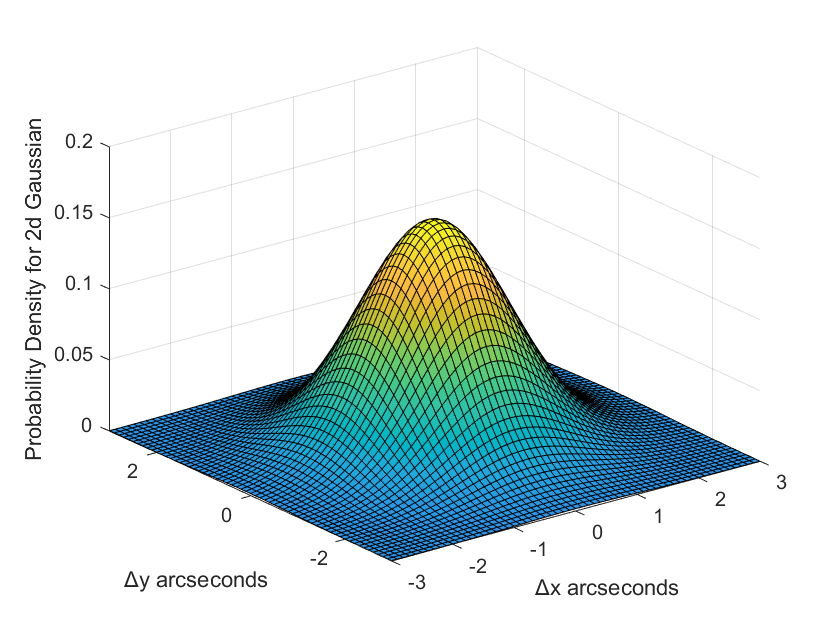

clc; clear; close all;
mu = [0 0];
sigma = [1 0; 0 1];

x1 = -3:0.1:3;
x2 = -3:0.1:3;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];

y = mvnpdf(X,mu,sigma);
y = reshape(y,length(x2),length(x1));
surf(x1,x2,y);
caxis([min(y(:))-0.5*range(y(:)),max(y(:))]);
axis([-3 3 -3 3 0 0.2]);
xlabel('Δx arcseconds');
ylabel('Δy arcseconds');
zlabel('Probability Density for 2d Gaussian');

For a moving object in the sky (such as an asteroid) a significant displacement is expected. There is still a small chance for the stationary background (the random fluctuations in measured displacements) to produce a large displacement when imaging a stationary object. We'd like to be fairly certain that what we detect is, in fact, an asteroid, and not some statistical anomaly that occurred when looking at something that wasn't moving.

- What radial distance from the origin (in arcseconds) will give us a 'five sigma' (1 in 3.5 million) probability threshold for the stationary star background to produce a displacement signal as (or more) asteroid-like than the real thing?

- In mathematical terms: what is the "z-value" radius for the 2d Gaussian that will produce a 1 in 3.5 million probability when integrating the 2d bivariate normal distribution starting from the boundary circle (radius of "z-value", centered on the origin) all the way out to infinity in the xy-plane. Because of the radial symmetry of the 2d Gaussian, we can simplify the double integral by integrating concentric shells along a radial path out.

                            $\int_z^{\infty } \rho \left(x,y\right)2\pi \mathrm{rdr}=3\ldotp 5E^{-6}$   ,   $\rho \;\left(x,y\right)=\frac{1}{2\pi \;}e^{-\frac{1}{2}\left\lbrack x^2 +y^2 \right\rbrack }$,      $x^2 +y^2 =r^2$

                           
$$\int_z^{\infty } {r*e}^{-\frac{1}{2}*r^2 } \mathrm{dr}=3\ldotp 5E^{-6}$$


We solve this integral for z to get the '5 sigma' threshold distance in arcseconds.

fun1 = @(r) r.*exp(-0.5*(r.^2));
fun2 = @(z) (integral(fun1,z,Inf)-(3.5*10^(-6)));
fzero(fun2,1)

ans = 5.0125

In this case, it looks to be about 5 arcseconds.

## Problem 3

Cosmic rays are charged particles that spiral through the magnetic fields of galaxies over great distances. Here on earth they fly in from all directions on twisting paths, but the high-energy particles that reach earth will, for significant speeds, be percieved as travelling in a straight line. When these are blocked by the sun and the moon they will form "holes" in the cosmic ray sky.

In a region of sky the size of a moon, we find that the rate of cosmic rays we measure is 1 per minute (random in time). We then observe the moon itself over a period of time (8 hours a day for 15 days, when it's not near the horizon) and we count a total of 6800 cosmic rays. We would like to find the significance of our observation.

- We ask: what is the probability of a moon sized patch of sky, over this period of time, producing a total cosmic ray count that looks as or more like what we measure (or expect to measure) when looking at the moon?

- The background probability distribution function describes an average rate for random events, which is precisely what a Poisson distribution models. Ours has a mean rate of 1 cosmic ray per minute for the moon-sized patch of unobstructed sky. We can then integrate (sum) this distribution for the length of time given (8 hours a day for 15 days) to get the probability distribution for the sum of the background to test against the measured value of 6800 cosmic rays when looking at the moon. When summing Poisson distributions, the resulting distribution's mean is the sum of the means of the distributions summed, so we can quickly calculate that the summed background has a mean rate of (1 ray per minute)*(60 minutes per hour)*(8 hours per day)*(15 days)=7200 cosmic rays over this time interval, and can produce the sum distribution directly with this value as its average rate. We expect the moon to block most cosmic rays, so "more signal-like" will be more towards 0 cosmic rays detected. We integrate from 0 to 6800 on the sum background probability distribution to get a probability for producing "signal-like" values in this region, and then we convert it into a sigma value by means of finding a z-value for that probability on a standard normal distribution.

clc; clear; close all;
sumrate = 1*60*8*15

sumrate = 7200

sumpoisson = makedist("Poisson","lambda",sumrate);
sig = cdf(sumpoisson,6800)

sig = 1.0133e-06

abs(norminv(sig))

ans = 4.7507

        3. We find that our moon shadow detection has a significance of just under 5 sigma. Assuming particle physics thresholds, this may suggest evidence of an asteroid (greater than 3 sigma) but is just short of the 5 sigma standard to be able to claim a discovery.